direction_names = ["FF","BF","FB","BB"];

s = sysf_two_link_lowRe;
nlinks = length(s.geometry.linklengths);

s = ensure_connection_and_metric(s); % required for create_grids
s = create_grids(s)

s = struct with fields:
      geometry: [1×1 struct]
          noop: 1
         n_dim: 1
        visual: [1×1 struct]
       physics: [1×1 struct]
             A: @(alpha1)LowRE_local_connection(s.geometry,s.physics,[alpha1])
        metric: @(alpha1)LowRE_dissipation_metric(s.geometry,s.physics,[alpha1])
    grid_range: [-3.1000 3.1000]
       density: [1×1 struct]
      tic_locs: [1×1 struct]
         A_num: @(alpha1)LowRE_local_connection(s.geometry,s.physics,[alpha1])
          grid: [1×1 struct]


a_grid = s.grid.eval{1};
adot_grid = s.grid.eval{1}*0.1;

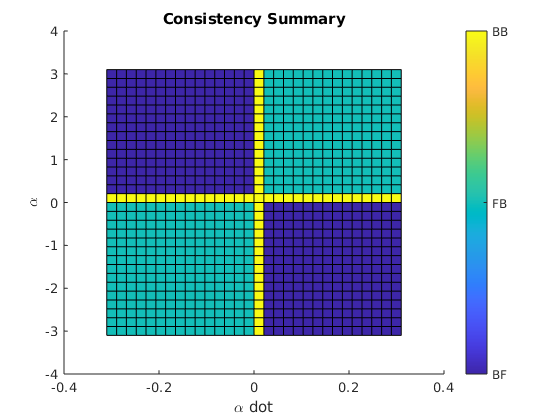

% find which system is consistent when
[system_map, count] = identify_piecewise_system(s, adot_grid);

% look at symmetry and missing/redundant areas
figure(5);
clf(5);
title("Consistency Summary");
xlabel("\alpha dot");
ylabel("\alpha");
surface(adot_grid, a_grid, system_map);
colorbar('Ticks',[1, 2, 3, 4],...
         'TickLabels',direction_names)

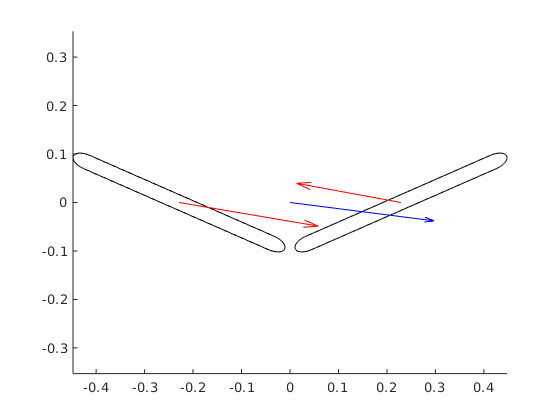

% get a body velocity
i = 20; j = 30;
bvel = apply_piecewise_system(s, system_map, 2, 0.1);

% get link velocities
lvel = zeros(nlinks, 3); % 3 is x y theta

% get Jfull(alpha)
[~, ~, J_full, ~, ~] = N_link_chain(s.geometry, a_grid(i));

for link = 1:nlinks
    lvel(link, :) = J_full{link} * [bvel; adot_grid(j)];
end

% plot
velocity_diagram(s, lvel, bvel, a_grid(i), adot_grid(j), 0, 0);

% define gait functions
centered_gait = generate_1D_gait(1, 0, 0);
offset_gait = generate_1D_gait(1, 1, 0);
offset_gait2 = generate_1D_gait(1, -1, 0);
tiny_gait = generate_1D_gait(0.5, 0, 0);
tiny_gait_bw = generate_1D_gait(0.5, 0, pi);
huge_gait = generate_1D_gait(3, 0, 0);
huge_gait_bw = generate_1D_gait(3, 0, pi);

gait = centered_gait;

% apply ODE solver
sol = asym_solve_gait(s, gait, system_map);
gait_displacement = deval(sol, 2*pi)

gait_displacement =     0.0670
    0.0012
    0.0004


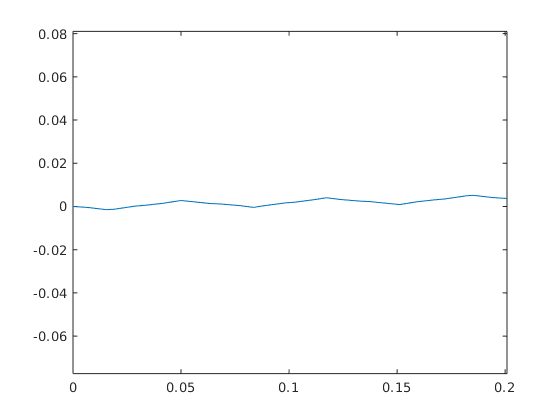

trajectory_plot(sol);

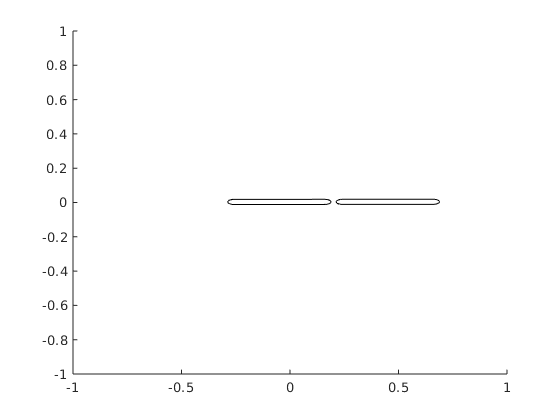

F = animate_asymmetric_solution(s, sol, gait);

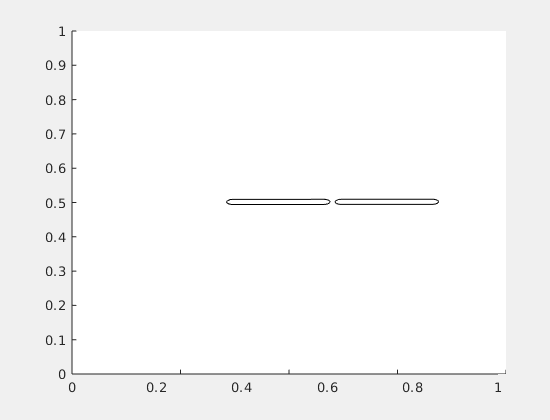

% play movie
figure('visible','on') %forces animation to be visible in live script
movie(F);

% write movie
%v = VideoWriter('AsymmetricFriction/offset_gait.avi');
%open(v);
%writeVideo(v, F);
%close(v);

% It's animating something!
% Things to do:
% - have body origin path traced out during animation
% - add motion blur
% - test with no-scales snake (physics check)

% plot A as a function of alpha:
A = get_A_of_alpha(s, a_grid);

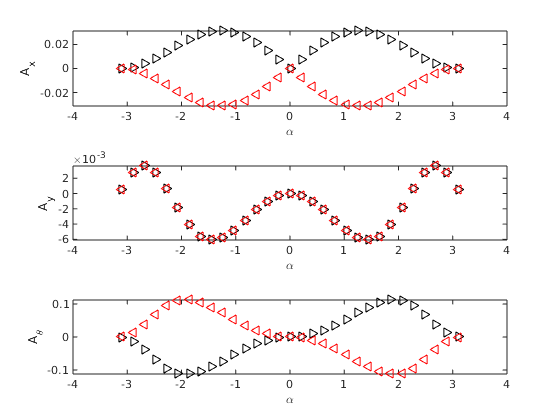

% directional glyphs
figure()
tiledlayout(3,1)

% X plot
ax1 = nexttile;
plot(ax1,a_grid, A.positive(:,1), 'k>', a_grid, A.negative(:,1), 'r<');
ylabel(ax1,'A_x')
xlabel(ax1,'\alpha')

% Y plot
ax1 = nexttile;
plot(ax1,a_grid, A.positive(:,2), 'k>', a_grid, A.negative(:,2), 'r<');
ylabel(ax1,'A_y')
xlabel(ax1,'\alpha')

% Theta plot
ax2 = nexttile;
plot(ax2,a_grid, A.positive(:,3), 'k>', a_grid, A.negative(:,3), 'r<');
ylabel(ax2,'A_\theta')
xlabel(ax2, '\alpha')

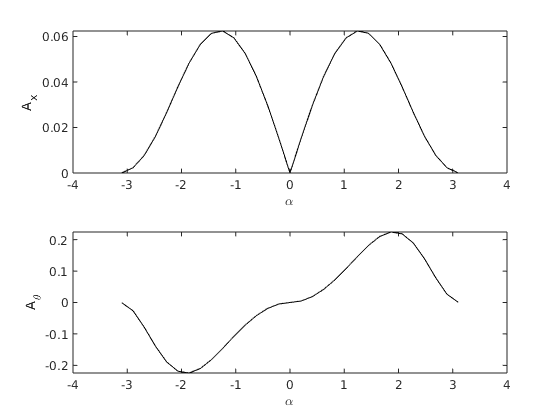


% directional glyphs
figure()
tiledlayout(2,1)

% X plot
ax1 = nexttile;
plot(ax1,a_grid, A.difference(:,1),'k')
ylabel(ax1,'A_x')
xlabel(ax1, '\alpha')

% Theta plot
ax2 = nexttile;
plot(ax2,a_grid, A.difference(:,3),'k')
ylabel(ax2,'A_\theta')
xlabel(ax2, '\alpha')

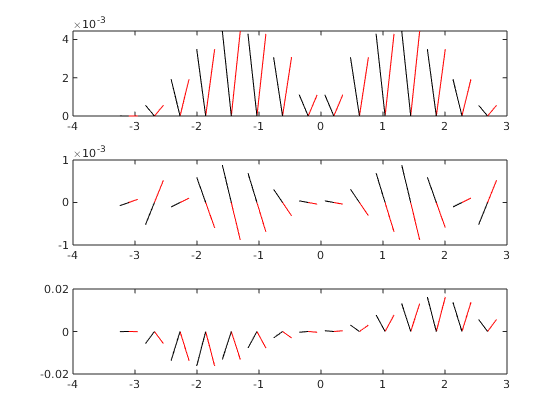

A_sparse = get_A_of_alpha(s, a_grid(1:2:31));
slope_plot(a_grid(1:2:31),A_sparse,true)

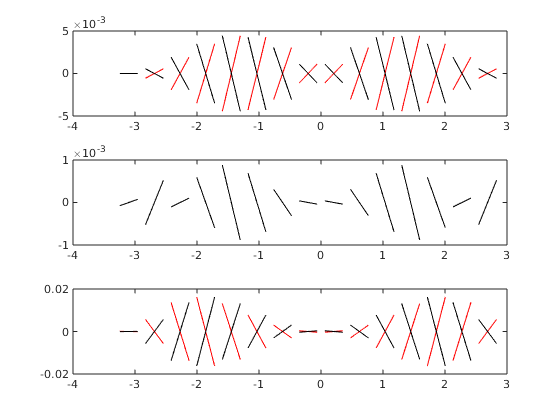

slope_plot(a_grid(1:2:31),A_sparse,false)

% compare a bunch of tiny gaits with different offsets
amp = 0.1;
step = 0.1;
off_grid = -pi+amp : step : pi-amp;

displacements = zeros([length(off_grid),3]);
for i = 1:length(off_grid)
    off = off_grid(i);
    gait = generate_1D_gait(amp, off, 1);
    sol = asym_solve_gait(s, gait, system_map);
    displacements(i,:) = deval(sol, 2*pi);
end
% figure()
% tiledlayout(3,1)
% ax = nexttile;
% plot(ax, off_grid, displacements(:,1))
% ax = nexttile;
% plot(ax, off_grid, displacements(:,2))
% ax = nexttile;
% plot(ax, off_grid, displacements(:,3))

% the backwards version:
displacements_bw = zeros([length(off_grid),3]);
for i = 1:length(off_grid)
    off = off_grid(i);
    gait = generate_1D_gait(0.5, off, -1);
    sol = asym_solve_gait(s, gait, system_map);
    displacements_bw(i,:) = deval(sol, 2*pi);
end
% figure()
% tiledlayout(3,1)
% ax = nexttile;
% plot(ax, off_grid, displacements_bw(:,1))
% ax = nexttile;
% plot(ax, off_grid, displacements_bw(:,2))
% ax = nexttile;
% plot(ax, off_grid, displacements_bw(:,3))

% compare forwards and then backwards to backwards and then forwards
difference = zeros([length(off_grid),3]);
for i = 1:length(off_grid)
    fw = vec_to_mat_SE2(displacements(i, :));
    bw = vec_to_mat_SE2(displacements_bw(i, :));
    fw_then_bw = fw * bw;
    bw_then_fw = bw * fw;
    difference(i,:) = mat_to_vec_SE2(fw_then_bw) - mat_to_vec_SE2(bw_then_fw);
end
amp

amp = 0.1000

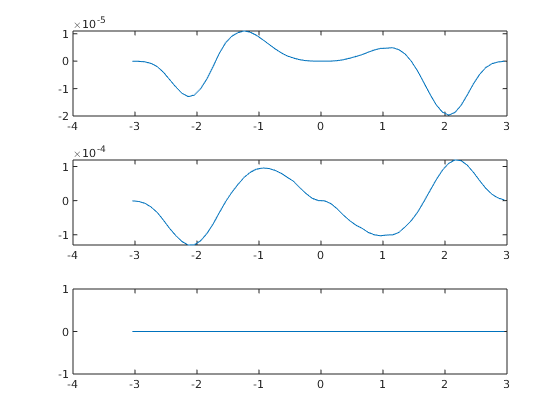

figure()
tiledlayout(3,1)
ax = nexttile;
plot(ax, off_grid, difference(:,1))
ax = nexttile;
plot(ax, off_grid, difference(:,2))
ax = nexttile;
plot(ax, off_grid, difference(:,3))

amp

amp = 0.1000

figure()
tiledlayout(3,1)
ax = nexttile;
plot(ax, off_grid, difference(:,1))
ax = nexttile;
plot(ax, off_grid, difference(:,2))
ax = nexttile;
plot(ax, off_grid, difference(:,3))

% need to do "gaits" that are linear from a to b and don't go back
% or is just taking the gait to pi instead of 2pi enough?

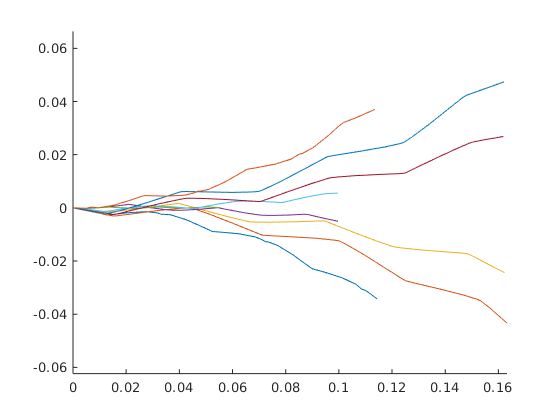

% testing out trajectory plots
figure()
hold on

amp = 0.5;
for off = -2:0.5:2

gait = generate_1D_gait(amp, off, 0);
sol = asym_solve_gait(s, gait, system_map);
trajectory_plot(sol);
end

hold off
axis equal

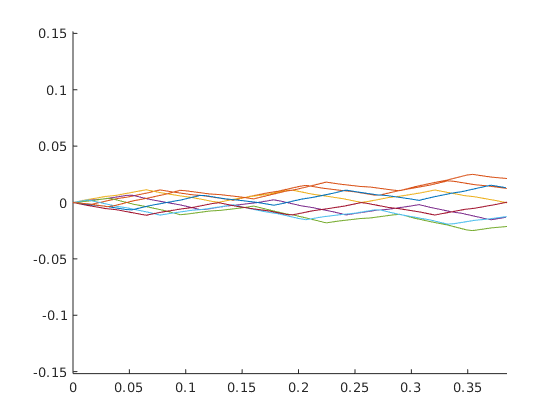

% comparing trajcetories of same gait, different phase
figure()
hold on

for phase = 0:pi/4:2*pi
    
    gait = generate_1D_gait(1.5, 0, phase);
    sol = asym_solve_gait(s, gait, system_map);
    trajectory_plot(sol)
    
end

hold off
axis equal

Ax_dif = A.difference(:,1);
Ay_dif = A.difference(:,2);
At_dif = A.difference(:,3);

point_a = a_grid(14)

point_a = -0.4133

point_b = a_grid(18)

point_b = 0.4133

da = a_grid(2) - a_grid(1)

da = 0.2067


dx = trapz(Ax_dif(14:18))*da

dx = 0.0125

dy = trapz(Ay_dif(14:18))*da

dy = 0

dth = trapz(At_dif(14:18))*da

dth = 0


% compare to a gait that goes from point_a to point_b:
off = (point_a + point_b)/2;
amp = abs(point_a - point_b)/2;
gait = generate_1D_gait(amp,off,0);
sol = asym_solve_gait(s, gait, system_map);

displacement = deval(sol, 2*pi)'

displacement =     0.0126    0.0000    0.0000



g_cerc_vector = [dx dy dth];
g_circ = [0 -g_cerc_vector(3) g_cerc_vector(1); ...
          g_cerc_vector(3) 0 g_cerc_vector(2); ...
          0 0 0];
Adif_prediction = mat_to_vec_SE2(expm(g_circ))

Adif_prediction =     0.0125         0         0



error = Adif_prediction - displacement

error = 	1.0e+-3 *

   -0.1416   -0.0169   -0.0293


proport_error = error ./ displacement

proport_error =    -0.0112   -1.0000   -1.0000


% test a bigger amp now that I think it's correct:
point_a = a_grid(11)

point_a = -1.0333

point_b = a_grid(21)

point_b = 1.0333

da = a_grid(2) - a_grid(1);

dx = trapz(Ax_dif(11:21))*da;
dy = trapz(Ay_dif(11:21))*da;
dth = trapz(At_dif(11:21))*da;

% compare to a gait that goes from point_a to point_b:
off = (point_a + point_b)/2;
amp = abs(point_a - point_b)/2;
gait = generate_1D_gait(amp,off,0);
sol = asym_solve_gait(s, gait, system_map);

displacement = deval(sol, 2*pi)'

displacement =     0.0709    0.0014    0.0004



g_cerc_vector = [dx dy dth];
g_circ = [0 -g_cerc_vector(3) g_cerc_vector(1); ...
          g_cerc_vector(3) 0 g_cerc_vector(2); ...
          0 0 0];
Adif_prediction = mat_to_vec_SE2(expm(g_circ))

Adif_prediction =     0.0702         0         0



error = Adif_prediction - displacement

error =    -0.0007   -0.0014   -0.0004


proport_error = error ./ displacement

proport_error =    -0.0097   -1.0000   -1.0000


% ode45 also for Adif
% then exp the result to get total displacement

% doesn't give us a trajectory-- ONLY an end position

% culomb gague refresh

% change system origin based on gait offset

% numerical integration
% quadriture
% or
% trapz